# Tarea 2: Profesor Laboret

Se comienza definiendo el sistema con el quie se trabaja:

p1 = 1;
p2 = -1;
K = 10;
G = zpk([],[p1 p2],K)

G =
 
      10
  -----------
  (s-1) (s+1)
 
Continuous-time zero/pole/gain model.



Se llama a la herramienta Sisotool, y allí se ajusta la ganancia, y con el cero que cancela al polo estable, se obtiene un sistema con el tiempo de establecimiento de 4 segundos solicitado en la consigna:

%sisotool(G)

Se obtiene $K_C =0\ldotp 2$.

%C
s = tf('s');
C = 0.2*(s+1)

C =
 
  0.2 s + 0.2
 
Continuous-time transfer function.



Se definen a continuación las constantes necesarias para simular el relé con histéresis en Simulink.

Kc = 0.2;
a = 1;
M = 1;
T = 0.1;
lineal = 1;
sim('bang_bang_hist_DI_PD')

Se grafica el error:

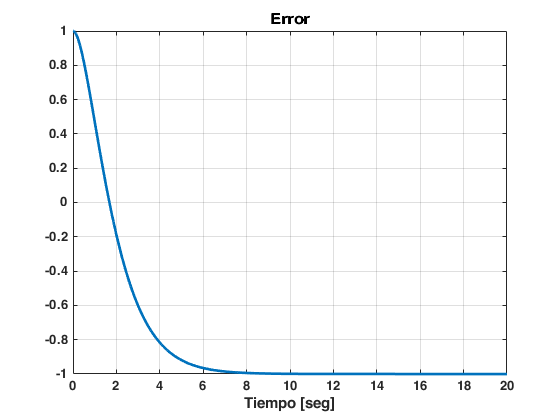

plot(tout,yout(:,1),'LineWidth',2) 
title('Error')
xlabel('Tiempo [seg]')
grid on

Ahora se muestra el plano de fases:

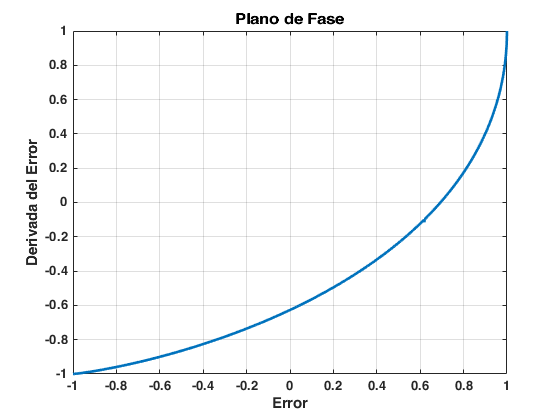

plot(yout(:,1),yout(:,3),'LineWidth',2) 
title('Plano de Fase')
xlabel('Error')
ylabel('Derivada del Error')
grid on

A continuación, la señal de control:

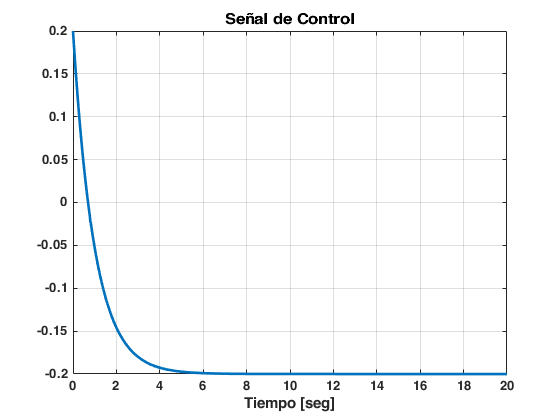

plot(tout,yout(:,2),'LineWidth',2) 
title('Señal de Control')
xlabel('Tiempo [seg]')
grid on

La salida del sistema es:

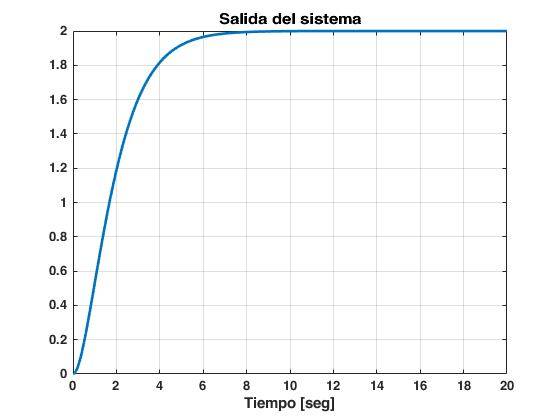

plot(ScopeData.time,ScopeData.signals.values,'LineWidth',2)
title('Salida del sistema')
xlabel('Tiempo [seg]')
grid on

Ahora, modificando el ancho de histéresis, la ganancia del relé y simulando un sistema no lineal, se obtiene:

M = Kc;
T = K*Kc/100;
lineal = 0;

Se obtienen de nuevo los gráficos para el nuevo sistema.

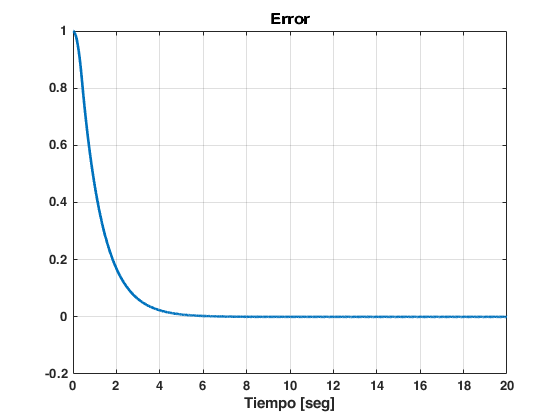

sim('bang_bang_hist_DI_PD')
plot(tout,yout(:,1),'LineWidth',2) 
title('Error')
xlabel('Tiempo [seg]')
grid on

El error minimo en la simulación es de:

minError = min(yout(:,1))

minError = -2.0543e-04

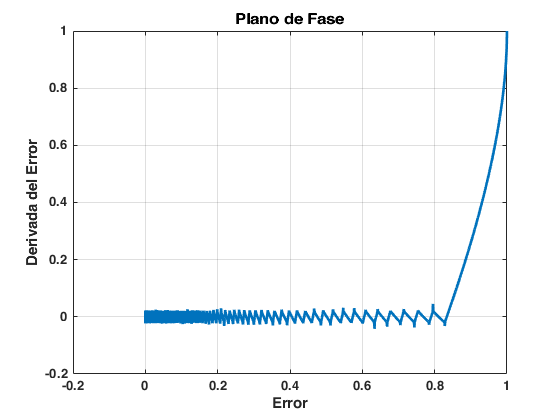

plot(yout(:,1),yout(:,3),'LineWidth',2) 
title('Plano de Fase')
xlabel('Error')
ylabel('Derivada del Error')
grid on

plot(tout,yout(:,2),'LineWidth',2) 
title('Señal de Control')
xlabel('Tiempo [seg]')

Se achica el límite en el eje horizontal, de modo de poder apreciar las oscilaciones con claridad.

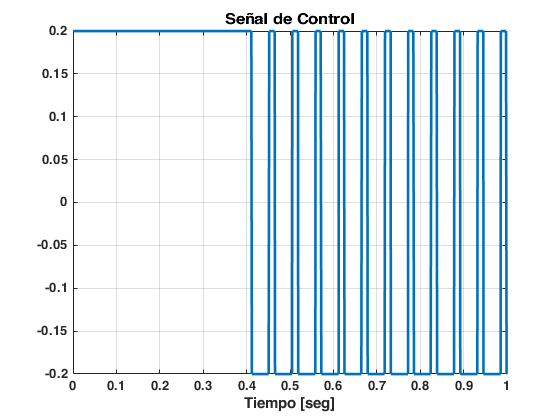

xlim([0 1])
grid on

plot(ScopeData.time,ScopeData.signals.values,'LineWidth',2)
title('Salida del sistema')
xlabel('Tiempo [seg]')
grid on

Se plantean dos nuevas situaciones:

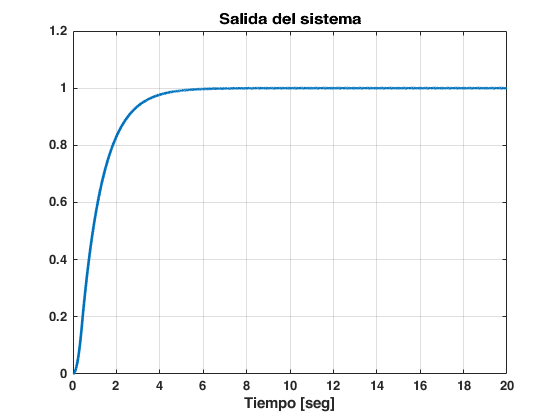

T = K*Kc/25;
sim('bang_bang_hist_DI_PD')

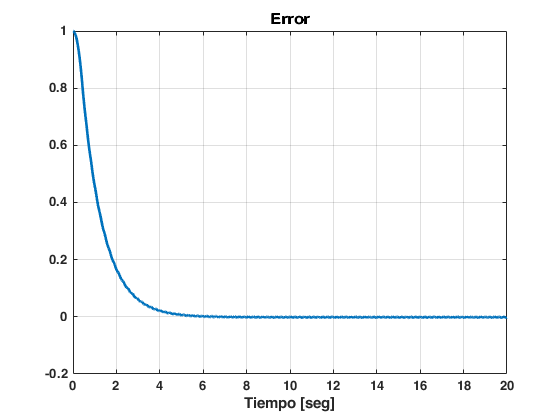

plot(tout,yout(:,1),'LineWidth',2) 
title('Error')
xlabel('Tiempo [seg]')
grid on

minError = min(yout(:,1))

minError = -0.0032

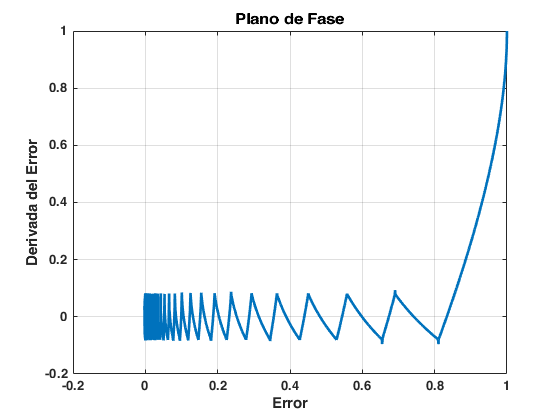

plot(yout(:,1),yout(:,3),'LineWidth',2) 
title('Plano de Fase')
xlabel('Error')
ylabel('Derivada del Error')
grid on

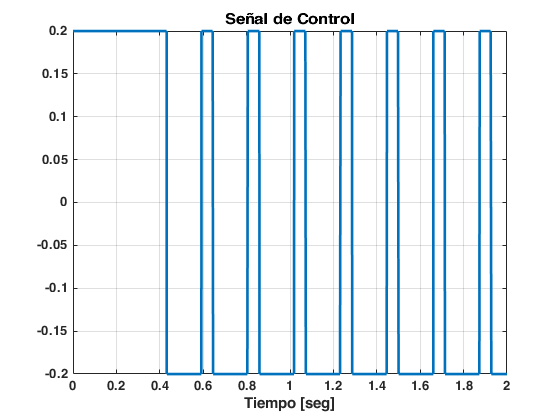

plot(tout,yout(:,2),'LineWidth',2) 
title('Señal de Control')
xlabel('Tiempo [seg]')
xlim([0 2])
grid on

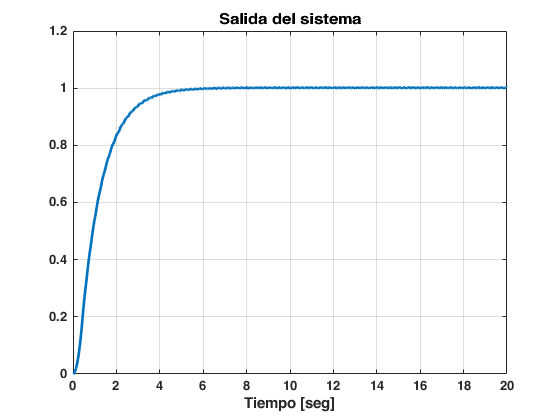

plot(ScopeData.time,ScopeData.signals.values,'LineWidth',2)
title('Salida del sistema')
xlabel('Tiempo [seg]')
grid on
T = K*Kc/10;
sim('bang_bang_hist_DI_PD')

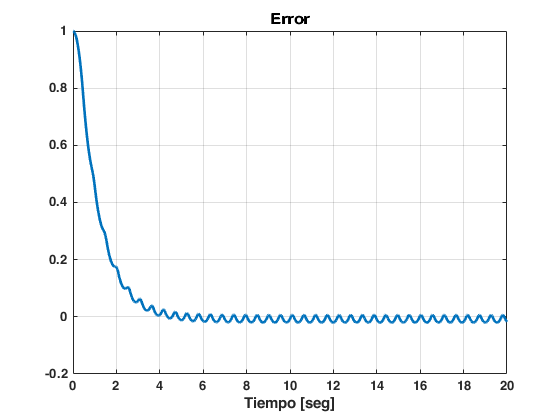

plot(tout,yout(:,1),'LineWidth',2) 
title('Error')
xlabel('Tiempo [seg]')
grid on

minError = min(yout(:,1))

minError = -0.0202

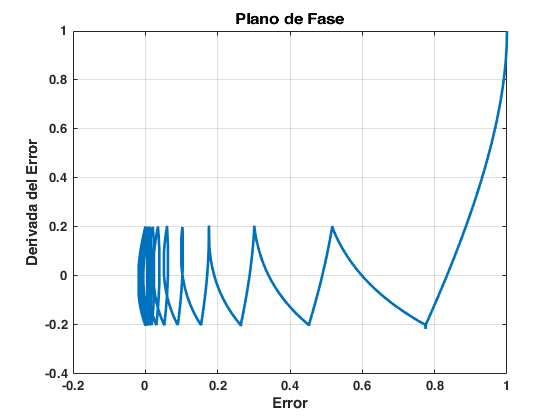

plot(yout(:,1),yout(:,3),'LineWidth',2) 
title('Plano de Fase')
xlabel('Error')
ylabel('Derivada del Error')
grid on

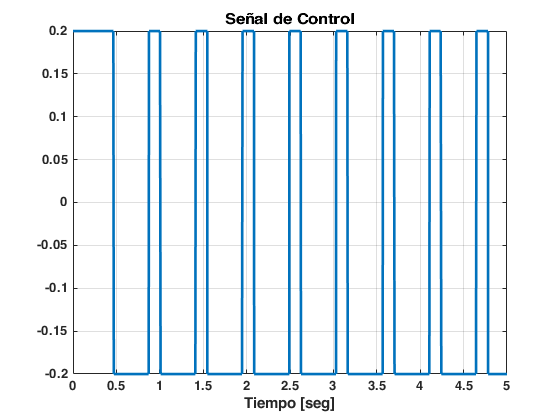

plot(tout,yout(:,2),'LineWidth',2) 
title('Señal de Control')
xlabel('Tiempo [seg]')
xlim([0 5])
grid on

plot(ScopeData.time,ScopeData.signals.values,'LineWidth',2)
title('Salida del sistema')
xlabel('Tiempo [seg]')
grid on

Finalmente, al subirse al ancho de histéresis a la ganancia total, se obtiene:

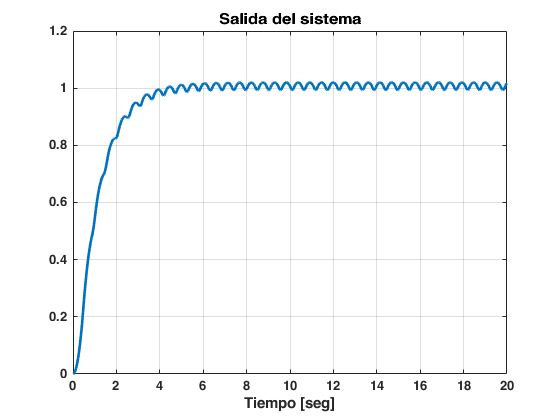

T = K*Kc;
sim('bang_bang_hist_DI_PD')

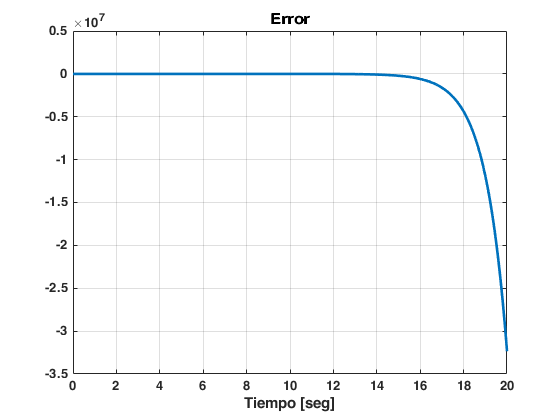

plot(tout,yout(:,1),'LineWidth',2) 
title('Error')
xlabel('Tiempo [seg]')
grid on

maxError = max(yout(:,1))

maxError = 1.3670

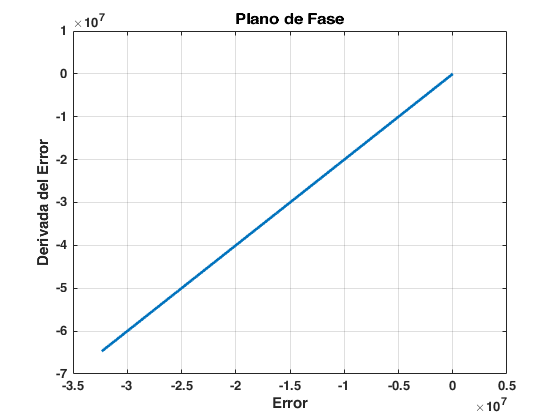

plot(yout(:,1),yout(:,3),'LineWidth',2) 
title('Plano de Fase')
xlabel('Error')
ylabel('Derivada del Error')
grid on

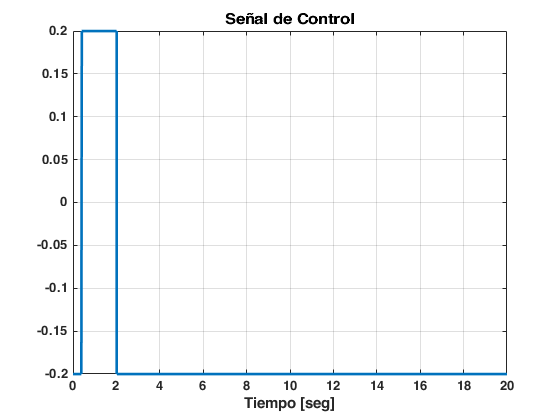

plot(tout,yout(:,2),'LineWidth',2) 
title('Señal de Control')
xlabel('Tiempo [seg]')
grid on

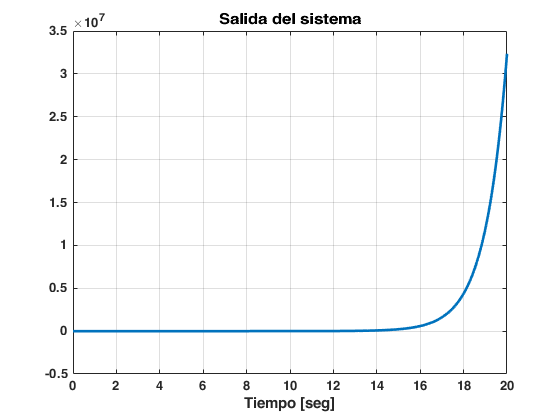

plot(ScopeData.time,ScopeData.signals.values,'LineWidth',2)
title('Salida del sistema')
xlabel('Tiempo [seg]')
grid on